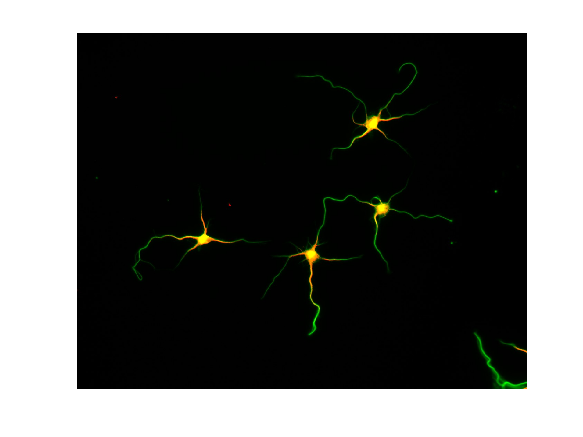

format longG

I = imread('2891.jpg');
I1 = imread('2986.jpg');
I_ = I ;
imshow(I,[])

[m, n, k] = size(I);

for d = 1: k % according to staining 
    I_(:,:,d) = mean_filter(I(:,:,d),4);    
end

ans =         1034        1304


ans =         1034        1304


ans =         1034        1304


%feature extraction(features can be used for cell detection)
%kse =  Haarlikefeature(I0(:,:,1), winL);
%Maximum level to which to perform the 2-D Haar transform, specified as a positive integer. The default value depends on the length of the input signal, x.
%If both the row and column sizes of x are powers of two, the 2-D Haar transform is obtained down to level log2(min(size(x))).
%If both the row and column sizes of x are even, but at least one is not a power of two, level is equal to floor(log2(min(size(x)/2))).
level = floor(log2(min(size(I_(:,:,1))/2)));
[a,h,v,d] = haart2(I_(:,:,1),level,'integer');

nn = 1;%length(h) choose batch size
ah = size(h{nn},1);
bh = size(h{nn},2);
winL1h = uint32(floor(m/ah));
winL2h = uint32(floor(n/bh));

av = size(v{nn},1);
bv = size(v{nn},2);
winL1v = uint32(floor(m/av));
winL2v = uint32(floor(n/bv));

ad = size(d{nn},1);
bd = size(d{nn},2);
winL1d = uint32(floor(m/ad));
winL2d = uint32(floor(n/bd));
%   [Imaxx, indx] = max(I_);% can be set according to the staining color as [R,G,B]
%    [Imaxy, indy] =
%    max(Imaxx);..................................................................................................-------------------------------------------------------------------------------------------------------------------------------------.......................................................................................................................................................................................................................................................................................................................................................................
%    indy = find(Imaxx == max(Imaxx));
I11 = I_(:, :, 1);
    I0 = zeros(size(I11));
%    threshold = 0.8*max(max(I11)); % Imaxy*0.05;
    lt =  0.8*(max(max(I11)));%max(max(I_))*0.05;
    
    
    I0(I11> lt) = I11(I11> lt);
    % label;
    Yh = getlb(I11, lt, ah, bh, winL1h, winL2h);
    Yv = getlb(I11, lt, av, bv, winL1v, winL2v);
    Yd = getlb(I11, lt, ad, bd, winL1d, winL2d);

%    Indx = indx(indy);
%    center = [Indx', indy'];
%    [idx, idy] = find(I_ >= threshold);
%    I0(idx, idy, 1)= 1;

% for n1 = 1:length(h)
%      Sh = repmat(0.0000001, [1, n1]);
%      Sh(n1)= features(h{n1});
% end
% for n2 = 1:length(v)
%      Sv = repmat(0.0000001, [1, n2]);
%      Sv(n2)= features(v{n2});
% end
% for n3 = 1:length(d)
%     Sd = repmat(0.0000001, [1, n3]);
%     Sd(n3)= features(d{n3});
% end
%S = [Sh;Sv;Sd];

S= [h{nn}(:)';v{nn}(:)';d{nn}(:)'];
kse = S;
Nn = size(S, 2);
F = kse;
%F = F(F> 0);   
Y = [Yh(1:Nn);Yv(1:Nn);Yd(1:Nn)];

W= repmat(1/3, [3, Nn]);
N = 50;
% sum(mean(F>0==(Y==1),1))
% sum(mean(F>mean(F,1)==(Y==1),1))
% sum(mean(abs(repmat(1,[1,Nn])./(1+exp(-F*Nn)))>0.5==(Y==1),1))
F(abs(repmat(1,[1,Nn])./(1+exp(-F/Nn)))>0.5)= 1;
F(abs(repmat(1,[1,Nn])./(1+exp(-F/Nn)))<0.5)= 0;
%F(F>=0)= 1;
%F(F<0)= 0;
Beta = W;
%adaboost
while N >0 
    change = 0;
    for l = 1:size(F,1)
        w = W(l,:);
        err = w.*abs(F(l,:) - Y(l,:));
        beta = err./(1-err);
        wt = w.*beta;
        wt = wt/sum(wt);
        errt = wt.*abs(F(l,:) - Y(l,:));
        if sum(err>errt)~= 0      
            err(err >errt) = errt(err >errt);
            W(l,err >errt) = wt(err >errt);
            Beta(l,err >errt) = beta(err >errt);
            change = l;
        end
    end
    N = N-1;
    if change == 0
        break;
    end
end
row = find(sum(Beta, 2) ~= 0,2);
Beta = Beta(row,:);
alpha = -log(Beta);
fnew = F(row,:); 
Ypred = sum(alpha.*fnew, 1);
Ylb = sum(Beta.*Y(row,:), 1);
YLB = zeros(1, size(Ylb,2));
YLB(Ylb >= 0.5*sum(Beta, 1)) = 1;
YLB(Ylb< 0.5*sum(Beta, 1)) = 0;
YPRED = zeros(1, size(Ypred,2));
YPRED (Ypred >= 0.5*sum(alpha, 1)) = 1;
YPRED (Ypred < 0.5*sum(alpha, 1)) = 0;

%Relu  
Gamma = W;
Beta = 0;
while N >0 
    change = 0;
    for l = 1:size(F,1)
        mu = mean(F(l,:),2);
        sigma2 = var(F(l,:));
        F_hat = (F(l,:)-mu)/sqrt(sigma2+0.000001);
        F_ = gamma*F_hat +beta; 
        w = W(l,:);
        err = w.*abs(F(l,:) - Y(l,:));
        beta = err./(1-err);
        wt = w.*beta;
        wt = wt/sum(wt);
        errt = wt.*abs(F(l,:) - Y(l,:));
        if sum(err>errt)~= 0      
            err(err >errt) = errt(err >errt);
            W(l,err >errt) = wt(err >errt);
            Beta(l,err >errt) = beta(err >errt);
            change = l;
        end
    end
    N = N-1;
    if change == 0
        break;
    end
end
row = find(sum(Beta, 2) ~= 0,2);
Beta = Beta(row,:);
alpha = -log(Beta);
fnew = F(row,:); 
Ypred = sum(alpha.*fnew, 1);
Ylb = sum(Beta.*Y(row,:), 1);
YLB = zeros(1, size(Ylb,2));
YLB(Ylb >= 0.5*sum(Beta, 1)) = 1

YLB =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


YLB(Ylb< 0.5*sum(Beta, 1)) = 0;
YPRED = zeros(1, size(Ypred,2));
YPRED (Ypred >= 0.5*sum(alpha, 1)) = 1

YPRED =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


YPRED (Ypred < 0.5*sum(alpha, 1)) = 0;


acc = sum(sum(YPRED == YLB))/length(Ylb);
train = YLB;
train(YLB == 1) = 255;
train = reshape(train, 515,650);
YPRED(YPRED == 1) = 255;
YPRED = reshape(YPRED, 515,650)

YPRED =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   25

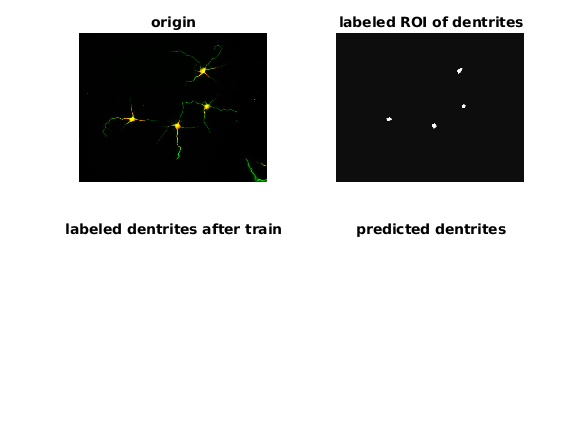



figure,
subplot(2,2,1)
imshow(imresize(I,0.5),[])
title('origin')
subplot(2,2,2)
imshow(imresize(I0,0.5),[])
title('labeled ROI of dentrites')
subplot(2,2,3)
imshow(train,[])
title('labeled dentrites after train')
subplot(2,2,4)
imshow(YPRED,[])
title('predicted dentrites')



[cx, cy] = find(I11> lt);
figure,
subplot(4,1,1)
scatter(cx,cy);
title('ROI points');  
subplot(4,1,2)
Z = linkage([cx, cy],'average','chebychev');
%Z = linkage([cx, cy],'ward','euclidean');
lastTen = Z(end-9:end,:)

lastTen =                       6056                      6093          15.1259489868371
                      6073                      6096          15.9718119006492
                      6092                      6094           16.884295347555
                      6087                      6099          17.1961673502871
                      6095                      6098          18.4544178029129
                      5662                      6017          106.595238095238
                      6097                      6101          203.804081632653
                      6102                      6104          326.221644433351
                      6100                      6105           431.70471920371
                      6103                      6106          702.997731547449


plot(lastTen(:,3))
title('ward distance v.s clusters')
subplot(4,1,3)
c = cluster(Z, "maxclust",4, 'Depth',4);
crosstab(c)

ans =          909
        1428
         688
          29


cutoff = median([Z(end-3,3) Z(end-2,3) Z(end-1,3)]);
dendrogram(Z,'ColorThreshold',cutoff)

subplot(4,1,4)
c1 = cluster(Z, "maxclust",6, 'Depth',8);
crosstab(c1)

ans =      8
    21
   588
   840
   909
   688


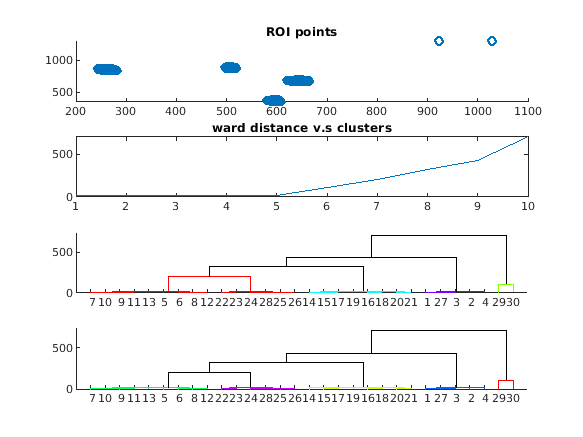

cutoff = median([Z(end-5,3) Z(end-4,3) Z(end-3,3) Z(end-2,3) Z(end-1,3)]);
dendrogram(Z,'ColorThreshold',cutoff)


%Relu SITF  
idN = 4;
eta =0.01;
w =1 /(idN+1);
[ctx, cty] = find(I11 > 0);
steps = 50;  
L = repmat(-100,[9, 1]);
l = zeros(9, length(ctx));
W = zeros(9, length(ctx));
B = zeros(9, length(ctx));
F_= zeros(9, length(ctx));
Mu = zeros(length(ctx), 1);
Eta = zeros(idN, idN);
Kse = zeros(idN, idN);
%    for k = 1:length(ctx)
    k = 1;
%    for k = 1:length(ctx)
%    for k = 1:7
%    for k = 59:length(ctx) 
%for k = 54:length(ctx) 
        while steps >0
            Itemp= I0(max(ctx(k)-1, 1):min(ctx(k)+1, m),max(cty(k)-1, 1):min(cty(k)+1, n)); 
            mu = mean(Itemp(:));
            sigma2 = var(Itemp(:)); 
            sigma = sqrt(sigma2);
            F_hat = (Itemp(:)-mu)./sqrt(sigma2+0.000001);
            
            if length(size(sigma*F_hat + mu, 1))==1    
                F_(1:size(F_hat,1), k) = repmat(length(size(sigma*F_hat + mu, 1)), size(F_hat));
            end

            w = ones(length(F_(1:size(F_hat,1), k)),1)./(1 + exp(-F_(1:size(F_hat,1), k)));
            b = ones(length(F_(1:size(F_hat,1), k)),1)./(1 + exp(-F_(1:size(F_hat,1), k) - sigma.*F_hat));
            w = w/(sum(w)+0.000001);
            wd = 1+exp(-F_(1:size(F_hat,1)));
            wd(isinf(wd)) = 10000;
            w = w + mu*F_hat.*wd.^2./(exp(-F_(1:size(F_hat,1), k)).*F(1:size(F_hat,1)+0.00001));
            b = b + mu*F_hat.*wd.^2./(exp(-F_(1:size(F_hat,1), k)-sigma.*F_hat).*F_(1:size(F_hat,1), k)+0.00001); 
            l(1:length(real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001))), k) = real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001));
%            L = real(-F_hat.*log(F_+0.000001));
            wt = w(real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001))> L(1:size(F_hat,1)));
            bt = b(real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001))> L(1:size(F_hat,1)));
            if sum(isnan(wt))~= length(wt) & sum(wt==0)~= length(wt)
                W(real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001))> L(1:size(F_hat,1), k), k) = wt;
            end
            if sum(isnan(bt))~= length(bt) & sum(bt==0)~= length(bt)
                B(real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001))> L(1:size(F_hat,1), k), k) = bt;
            end
            Mu(k)=  mean(W(1:size(F_hat,1), k).*F_(1:size(F_hat,1), k)+ B(1:size(F_hat,1), k));
            L = real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001));
            if (sum(isnan(wt))== length(wt) | sum(wt==0)== length(wt)) & (sum(isnan(bt))== length(bt) | sum(bt==0)== length(bt))
                k = k+1;
                step = 50;
%                break;
            end
            steps = steps -1;
            if steps == 0
                k = k+1;
                step = 50;
%                break;
            end
            if k > length(ctx)
                break;
            end
        end

%        if k > length(ctx)
%            break;
%        end
        
%end
     W(real(-F_hat.*log(F_(1:size(F_hat,1), :)+0.000001))> L(1:size(F_hat,1)),:) = w(real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001))> L(1:size(F_hat,1)));
     B(real(-F_hat.*log(F_(1:size(F_hat,1), :)+0.000001))> L(1:size(F_hat,1)), :) = b(real(-F_hat.*log(F_(1:size(F_hat,1), k)+0.000001))> L(1:size(F_hat,1)));
%     F_ = real(-log(ones(size(W))./W));
%     l =real( (W-B)./F_.*log(F_));
%     l = l(:);
%     l(isnan(l))=0;
%     l = reshape( l, size(F_));
     W = W(:);
     W(isnan(W))=0;
     W = reshape( W, size(l));
     B = B(:);
     B(isnan(B))=0;
     B = reshape( B, size(W));
   %  Mu = mean(W(1:size(F_hat,1),k).*F_(1:size(F_hat,1),k) + B(1:size(F_hat,1),k));
   %  l = Mu.*log(F_(1:size(F_hat,1),k)+0.000001);
     Mu = mean(W(1:size(F_hat,1),k).*F_(1:size(F_hat,1),k) + B(1:size(F_hat,1),k));
     l = Mu.*log(F_(1:size(F_hat,1),k)+0.000001);


    Mu = (Mu-mean(Mu))/(std(Mu)+0.000001);
    if length(size(Mu))==1
        Mup = ones(length(B),1)/(1+exp(-Mu'));
    else
        Mup = ones(length(Mu),1)./(1+exp(-Mu'));
    end
    cond1 = sum(Mup~=0)~=  0;
    l(isnan(l)) == 0;
%     if sum(W~= 0, 1)~=0&sum(B~=0,1)~=0&cond1 == 0
%         break;
%     end
    Mu = (Mu-mean(Mu))/std(Mu);
    Mup = ones(length(Mu),1)./(1+exp(-Mu'));
    cond1 = sum(Mup~=0)~=  0;
    [l_s, l_i] = sort(l(sum(W~= 0,1)~=0&sum(B~=0,1)~=0&cond1));
    K = zeros(size(W,1), idN);
    if length(l_i)-idN+1> 0
        K(2:size(W,1),: ) = eta*abs((W(2: size(W,1), ctx(l_i(length(l_i)-idN+1:length(l_i)))) - W(1: size(W,1)-1, ctx(l_i(length(l_i)-idN+1:length(l_i)))))./(W(2: size(W,1), ctx(l_i(length(l_i)-idN+1:length(l_i)))) - W(1: size(W,1)-1, ctx(l_i(length(l_i)-idN+1:length(l_i))))+0.00001));
    end
    for i = 1: length(ctx)
        j= ctx(l_i(length(l_i)-idN+1:length(l_i)));
%        for j1 = ctx(l_i(length(l_i)-idN+1:length(l_i)))
         for j1 = 1:length(j)
            for j2 =  1:length(j)
                delta(j1, j2) = sqrt(mean((abs(Mup(i)-Mup(j1))-abs(Mup(i)-Mup(j2))).^2));  
                phi = K(:,j1) + K(:,j2).*Mup(j1).*Mup(j2);
                psi = mean(var(B)+var(W).*(var(B)+var(W)/9))/(2*pi).*(sin(acos(cov(Mup(j1),Mup(j2))))+cov(Mup(j1),Mup(j2)).*(pi-acos(cov(Mup(j1),Mup(j2)))));
            end 
        end
    end

Array indices must be positive integers or logical values.

    Eta = delta - max(mean(delta));
    Kse = cov(delta);
%end
 phi1 = exp(-(Eta).^2./(2*max(Kse)));  
 phi2 = 2*sum(exp(-(Eta).^2./(2*max(Kse))));  
 
 figure,
 subplot(2,2,1)
 imagesc( Eta)
 title('Eta')
 colorbar
 subplot(2,2,2)
 imagesc( Kse) 
 title('Kse')
 colorbar
 for i = 1:size(phi1,2)
    phi1s(:,i) = ones(size(phi1, i),1)./(1+exp(-phi1(:, i)));
 end
 subplot(2,2,3)
 plot(phi1s(:,2:4))
 title('ph1')
  subplot(2,2,4)
 plot( phi2,'o')
 title('ph2') 
 

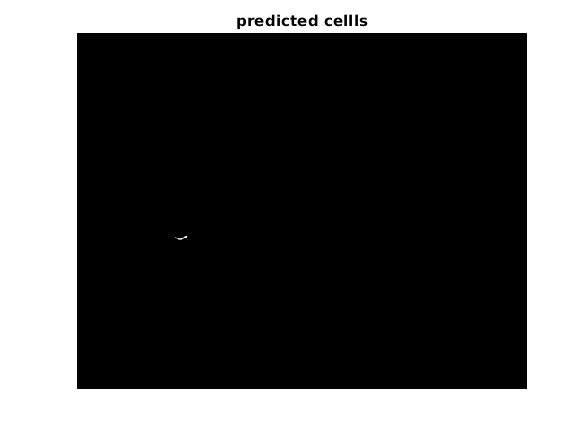

% logistic regression with regulation
idN = 4;
epsl =0.01;
w = ones(9, 1)./9;
lmd = w;
[ctx, cty] = find(I11 > 0);
steps = 50;  
L = repmat(-100,[9, 1]);
l = zeros(9, length(ctx));
ypred = zeros(1, length(ctx));
Ipred = zeros(size(I0));
W = zeros(9, length(ctx));
% B = zeros(9, length(ctx));
% F_= zeros(9, length(ctx));
% Mu = zeros(length(ctx), 1);
% Eta = zeros(idN, idN);
% Kse = zeros(idN, idN);
y = I0;
y(I11== max(max(I11))) = 1;
y(I11~= max(max(I11))) = -1;
    for k = 1:length(ctx)
%    k = 1;
%    for k = 1:length(ctx)
%    for k = 1:7
%    for k = 59:length(ctx) 
%for k = 54:length(ctx) 
        while steps >0
            Itemp= I0(max(ctx(k)-1, 1):min(ctx(k)+1, m),max(cty(k)-1, 1):min(cty(k)+1, n)); 
            Itemp = (Itemp - mean(mean(Itemp)))/std(mean(Itemp));
            Y = y(max(ctx(k)-1, 1):min(ctx(k)+1, m),max(cty(k)-1, 1):min(cty(k)+1, n));
            b = gampdf(Itemp(:), 0.2, 2);
%             b = ones(length(F_(:, k)),1)./(1 + exp(-F_(:, k) - sigma.*F_hat));
%             w = w/(sum(w)+0.000001);
%             wd = 1+exp(-F_);
%             wd(isinf(wd)) = 10000;
%             w = w + mu*F_hat.*wd.^2./(exp(-F_(:, k)).*F_+0.00001);
%             b = b + mu*F_hat.*wd.^2./(exp(-F_(:, k)-sigma.*F_hat).*F_+0.00001);   
            K =  abs( Itemp(:)); 
            l(1:length(K), k) = log(1 + exp(-Y(:) .* w(1:length(K)).* Itemp(:))) + lmd(1:length(K)).*w(1:length(K)).^2/2 + 2*K.*b.* Itemp(:)./(epsl*length(K));
            cond = log(1 + exp(-Y(:) .* w(1:length(K)).* Itemp(:))) + lmd(1:length(K)).*w(1:length(K)).^2/2 + 2*K.*b.* Itemp(:)./(epsl*(1:length(K)))> L(1:length(K));
            if sum(isnan(cond))~= length(cond) & sum(cond==0)~= length(cond)
                W(1:length(K),k) = -Y(:) .*Itemp(:)./(1 + exp(-Y(:) .* w(1:length(K)).* Itemp(:)));
            end
            if (sum(isnan(cond))== length(cond) | sum(cond==0)== length(cond)) 
                k = k+1;
                steps = 50;
                break;
            end
            w = W(:, k);
            L = log(1 + exp(-Y(:) .* w(1:length(K)).* Itemp(:))) + lmd(1:length(K)).*w(1:length(K)).^2/2 + 2.*K.*b(1:length(K)).* Itemp(:)./(epsl*(1:length(K)));
            steps = steps -1;
            if steps == 0
                l(isnan(l(:,k)),k) = 0.5*l(isnan(l(:,k)),max(k-1,1))+0.5*l(isnan(l(:,k)),min(k+1,n));
                l(sum(isnan(l(:,k)))==size(l,1),k) = 0.5*l(sum(isnan(l(:,k)))==size(l,1),max(k-1,1))+0.5*l(sum(isnan(l(:,k)))==size(l,1),min(k+1,n));
                ypred(1,k) = mean(l(l(:,k)~=0,k));
                k = k+1;
                steps = 50;
                Ipred(ctx(k),cty(k)) = mean(L(L>0));
                break;
            end
%             if k > length(ctx)
%                  break
%             end
         end
         if k > length(ctx)
             break
         end
    end

 
 Ipred(ctx(ypred~=0),cty(ypred~=0)) = I11(ctx(ypred~=0),cty(ypred~=0));

 figure,
 imshow(Ipred,[])
 title('predicted cellls')


 accuracy = sum(sum(Ipred == I11))./(m*n);
 
  %
  Ipred= imresize(Ipred, 0.1);
  I11 = imresize(I11, 0.1);
  Ipred= sparse(double(Ipred(:)));
  I11 = sparse(double(I11(:)));
 [h, p] = ttest(Ipred , I11)

h =      1


p =       9.58933251241937e-65


 
  %discrete
  
 pcd = I11/max(I11);
 yc = ones(1,length(pcd))./(1+exp(-pcd));
 yc1 = ones(1,length(pcd))./(1+exp(-pcd-log(1)));
 
 pred = Ipred/max(Ipred);
 ypred = ones(1,length(pred))./(1+exp(-pred));
 ypred1 = ones(1,length(pred))./(1+exp(-pred-log(1)));

 [h, p] = ttest(yc, ypred)% h = 1, significantly different

h =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


p =       1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.43317437830777e-64      1.


%F0
 fa_ac = (yc+pcd).*(ypred+pred);
 %F01
 fa_ac1 = (yc1+pcd).*(yc1-pcd*log(1));
 %F10
 f1a1_ac = (ypred-pred*log(1)).*(ypred+pred);
 %F1
 f1a1_ac1 = (yc-pcd*log(1)).*(ypred-pred*log(1));


 
 % fk = (gam(1) - pad(1:4).*log(1.1)).*(gam(2) - pacd(1:4).*log(1.1));
 F0 = [mean(fa_ac(:)), mean(fa_ac1(:))];
 F1 = [mean(f1a1_ac(1)), mean(f1a1_ac1(1))];

Unrecognized function or variable 'f1a_ac'.

 

 nH = sum([ttest(F0(1),F1(1))==0 ,ttest(F0(2),F1(1))==0 ,ttest(F0(1),F1(2))==0 ,ttest(F0(2),F1(2))==0]);
 phi =  3/4+0.5*nH/4
 psi = 0.5+0.5*(3/4-1/4)
 
 phi_ = mean(f1a1_ac1)-mean(fa_ac)+0.5
 psi_ = max(F0(:)-F1(:))
 
 
 
 

 
  %
 
 a_80 = [-4, -3, -2, -1, 2, 2, 3, 3, 6, 7 ,7, 10, 14, 14, 17, 18, 24, 26, 29, 30, 31, 55, 72];
 a_80c = [30, 33, 36, 47, 47, 48, 48, 49, 58, 60, 64, 64, 67, 72, 75, 76, 77, 79, 84, 86, 86, 88, 88, 89, 96];
 
 theta = 1;
 K =2;
 %discrete
 pad = a_80/max(a_80);
 ya = ones(1,length(pad))./(1+exp(-pad));
 ya1 = ones(1,length(pad))./(1+exp(-pad-log(theta)));
  
 pacd = a_80c/max(a_80c);
 yac = ones(1,length(pacd))./(1+exp(-pacd));
 yac1 = ones(1,length(pacd))./(1+exp(-pacd-log(theta)));   

[h, p] = ttest(ya, yac(1:23))% h = 1, significantly different

h = 1

p = 5.1598e-13

 
 gam=[-3.101, 0.9425];
 %F0
 fa_ac = (ya+pad).*(yac(1:23)+pacd(1:23));
 %F01
 fa_ac1 = (ya+pad).*(yac1(1:23)-pacd(1:23)*log(1));
 %F10
 f1a1_ac = (ya1-pad*log(1)).*(yac(1:23)+pacd(1:23));
 %F1
 f1a1_ac1 = (ya1-pad*log(1)).*(yac1(1:23)-pacd(1:23)*log(1));

 
 % fk = (gam(1) - pad(1:4).*log(1.1)).*(gam(2) - pacd(1:4).*log(1.1));
 F0 = [mean(fa_ac(:)), mean(fa_ac1(:))];
 F1 = [mean(f1a1_ac(1)), mean(f1a1_ac1(1))];
 

 nH = sum([ttest(F0(1),F1(1))==0 ,ttest(F0(2),F1(1))==0 ,ttest(F0(1),F1(2))==0 ,ttest(F0(2),F1(2))==0]);
 phi =  3/4+0.5*nH/4;
 psi = 0.5+0.5*(3/4-1/4);
 
 phi_ = mean(F0(:))-mean(F1(:))+0.5

phi_ = 0.9420

 psi_ = max(F0(:)-F1(:))

psi_ = 0.6463

 
figure,
subplot(4,1,1)
plot(log(fa_ac));
title('00');
subplot(4,1,2)
plot(log(fa_ac1));
title('11');
subplot(4,1,3)
plot(log(f1a1_ac));
title('10');
subplot(4,1,4)
plot(log(f1a1_ac1));
title('11');
figure,
imagesc([F0;F1])
title('phi,psi')
